% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

k = 3;
d = 8;

options.method = "standard";
options.lambda = 5;

[T, O, pi] = generateHMM(k, d, 1, options);

T =     0.8000    0.0667    0.1667
    0.1000    0.8667    0.1667
    0.1000    0.0667    0.6667


O =     0.4000    0.0500    0.0200
    0.0667    0.5500    0.0200
    0.0667    0.0500    0.0200
    0.0667    0.0500    0.4200
    0.0667    0.0500    0.4200
    0.0667    0.0500    0.0200
    0.0667    0.0500    0.0200
    0.2000    0.1500    0.0600


pi =     0.3226    0.4839    0.1935


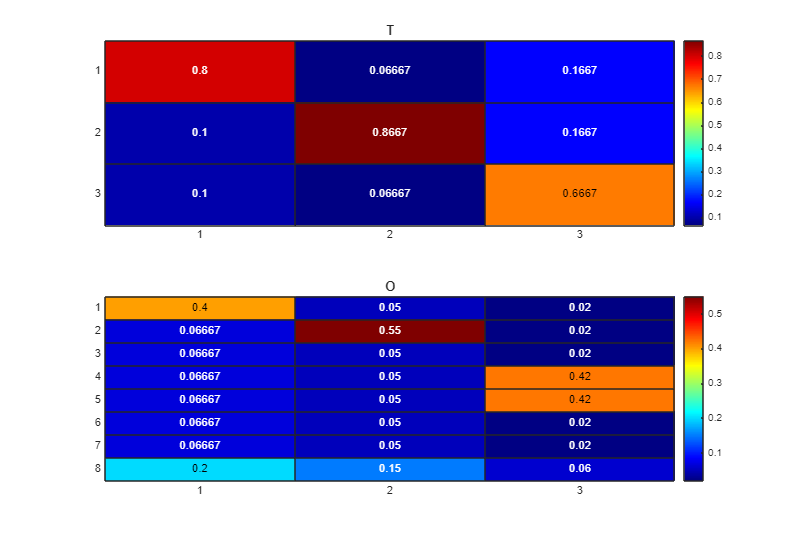



figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

eig(T)

ans =     1.0000
    0.7549
    0.5785


Generate an observational sequence based on the defined HMM

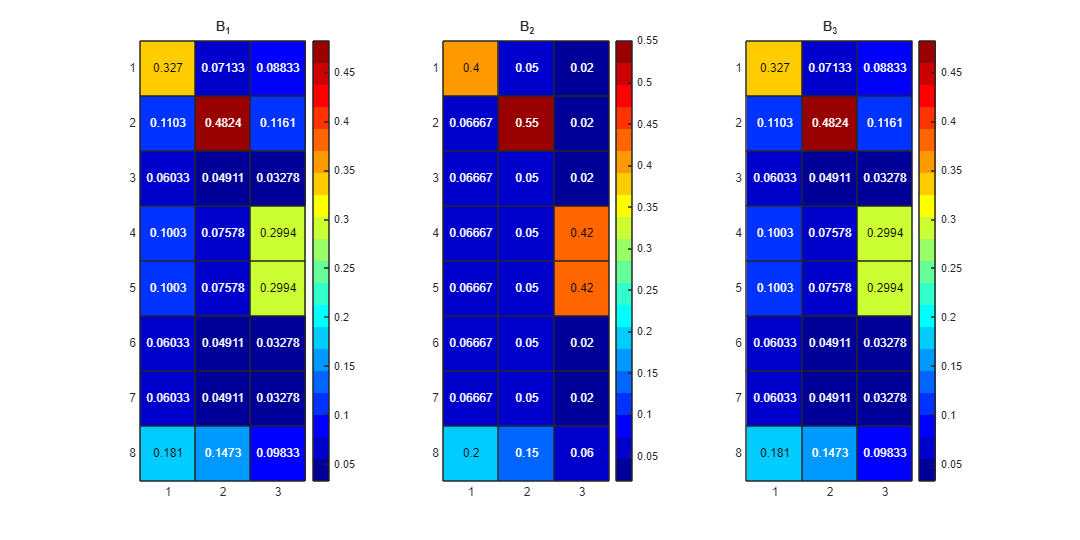

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

D = {};
D{1} = Stochasticize(O * diag(pi) * T' / inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);

PlotFactorMatrices(D);


% 
% P3 = cpdgen(U);
% 
% [V, D, W] = eig(T);
% mu = abs(W(:, 1));
% mu = mu ./ sum(mu);
% P2 = O' * T * diag(mu) * O;

Generate Probability Density Tensors

tic
P3 = ProbabilityTensorGenerate(seq, 3, d);
toc

Elapsed time is 0.462553 seconds.




max_iters = 1000;
rho = 1/3;

tic
[B1, B2, B3, output] = structural_constraint_cpd(P3, k, rho, max_iters);
toc

Elapsed time is 0.190898 seconds.


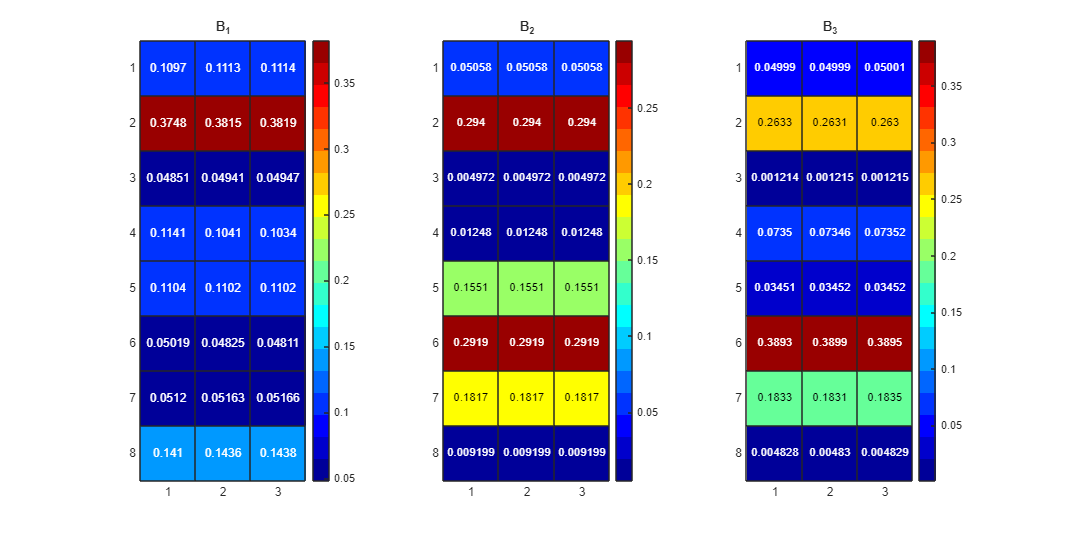


PlotFactorMatrices({B1, B2, B3})


B1 = Stochasticize(B1);
B2 = Stochasticize(B2);
B3 = Stochasticize(B3);

P_best = PermutationFitEmission(O, B2);

B1 = B1 * P_best';
B2 = B2 * P_best';
B3 = B3 * P_best';

T_hat = Stochasticize(pinv(B2) * B3);
T_hat = P_best * T_hat * P_best';


norm(T-T_hat, "fro") + norm(O-B2, "fro")

ans = 1.8012

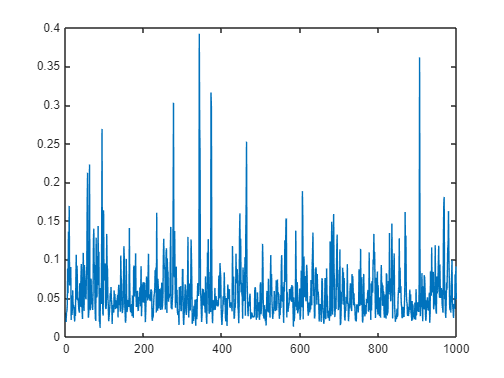


figure()
plot(output.relerr)

PlotFactorMatrices({B1, B2, B3})

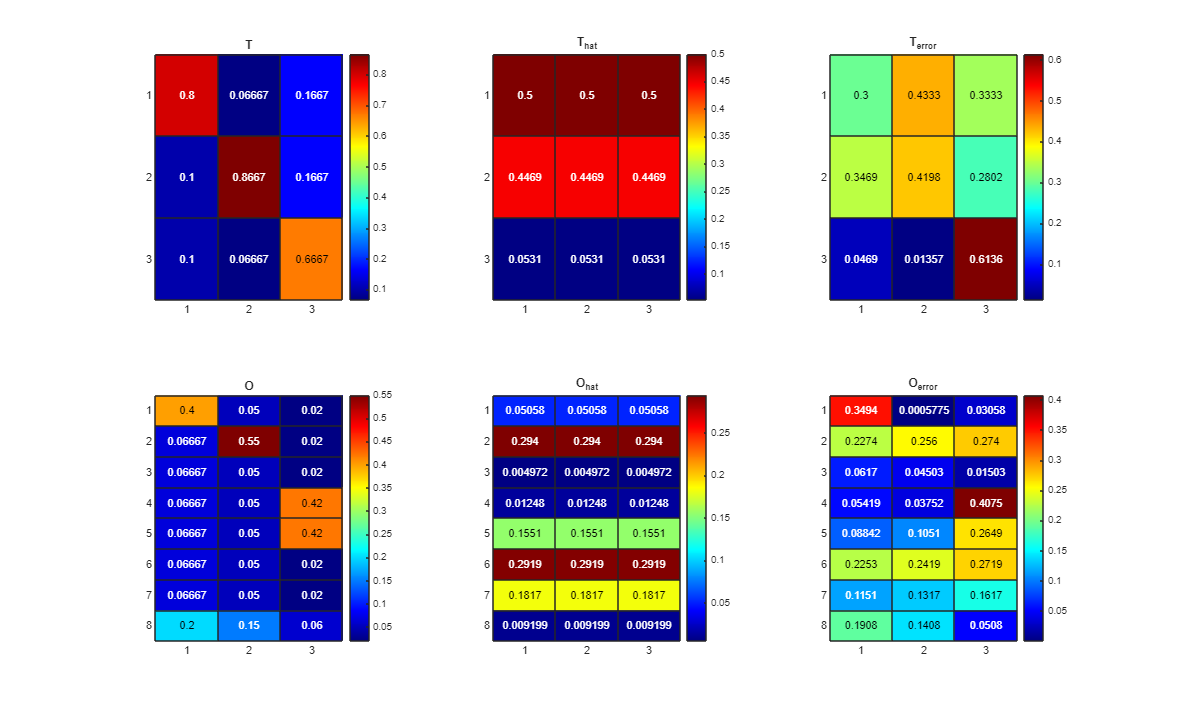

plotHMMError(T, T_hat, O, B2)